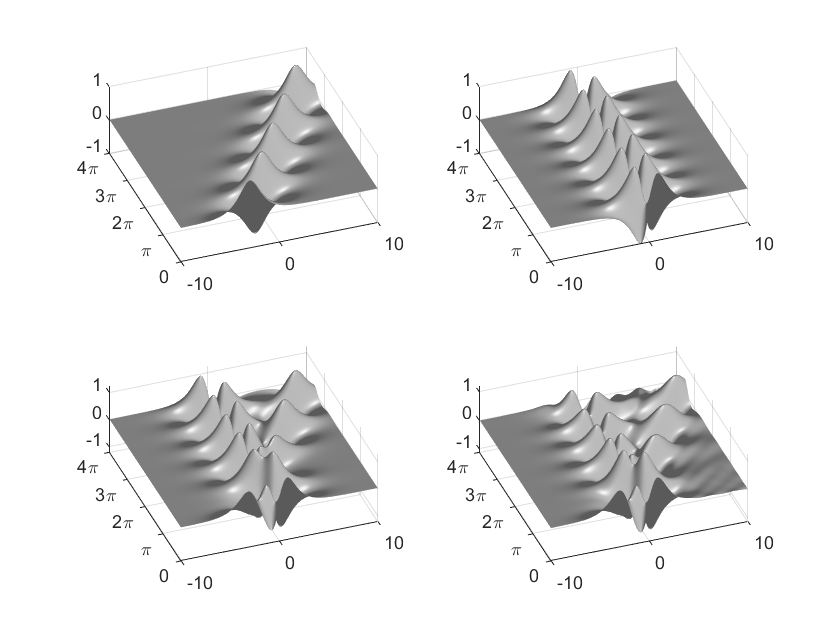

%% Define time and space discretizations
xi = linspace(-10,10,400) ;
t = linspace (0,4*pi,200);
dt = t(2) - t(1);
[Xgrid ,T] = meshgrid(xi,t);
%% Create two spatiotemporal patterns
f1 = sech(Xgrid+3-T) .* (1*exp(1j*2.3*T));
%f1 = sin(Xgrid+3) .* (1*exp(1j*2.3*T));
f2 = (sech(Xgrid).*tanh (Xgrid)).*(2*exp(1j*2.8*T));
%% Combine signals and make data matrix 
f = f1 + f2;
X = f.'; % Data Matrix

%% Visualize f1, f2, and f
figure;
subplot(2,2,1);
surfl(real(f1));
shading interp; colormap(gray ); view (-20,60);
set(gca , 'YTick', numel(t)/4 * (0:4)),
set(gca , 'Yticklabel',{'0','\pi','2\pi','3\pi','4\pi'});
set(gca , 'XTick', linspace(1,numel(xi),3)),
set(gca , 'Xticklabel',{'-10', '0', '10'});
subplot(2,2,2);
surfl(real(f2));
shading interp; colormap(gray ); view (-20,60);
set(gca , 'YTick', numel(t)/4 * (0:4)),
set(gca , 'Yticklabel',{'0','\pi','2\pi','3\pi','4\pi'});
set(gca , 'XTick', linspace(1,numel(xi),3)),
set(gca , 'Xticklabel',{'-10', '0', '10'});
subplot(2,2,3);
surfl(real(f));
shading interp; colormap(gray ); view (-20,60);
set(gca , 'YTick', numel(t)/4 * (0:4)),
set(gca , 'Yticklabel',{'0','\pi','2\pi','3\pi','4\pi'});
set(gca , 'XTick', linspace(1,numel(xi),3)),
set(gca , 'Xticklabel',{'-10', '0', '10'});


% my code
dmd = DynamicModeDecomposer(X,"rank",-1,"delta_t",dt);
myX_dmd = dmd.reconstructedSnapshots;
% end my code


%% Create DMD data matrices
X1 = X(:, 1:end -1);
X2 = X(:, 2:end);
%% SVD and rank-2 truncation
r = 2; % rank truncation
[U, S, V] = svd(X1, 'econ');
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);
%% Build Atilde and DMD Modes
Atilde = Ur'*X2*Vr/Sr;
[W, D] = eig(Atilde);
Phi = X2*Vr/Sr*W; % DMD Modes
%% DMD Spectra
lambda = diag(D);
omega = log(lambda)/dt;
%% Compute DMD Solution
x1 = X(:, 1);
b = Phi\x1;
time_dynamics = zeros(r,length(t));
for iter = 1:length(t)
time_dynamics (:,iter )=(b.*exp(omega*t(iter )));
end
X_dmd = Phi*time_dynamics ;



% sort of my code

subplot(2,2,4);
surfl(real(myX_dmd'));
shading interp; colormap(gray ); view (-20,60);
set(gca , 'YTick', numel(t)/4 * (0:4)),
set(gca , 'Yticklabel',{'0','\pi','2\pi','3\pi','4\pi'});
set(gca , 'XTick', linspace(1,numel(xi),3)),
set(gca , 'Xticklabel',{'-10', '0', '10'});

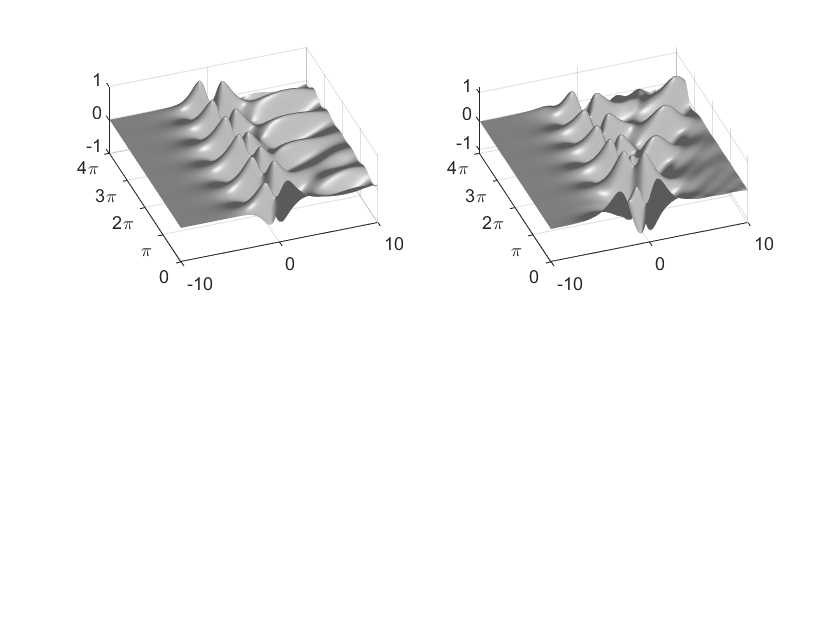


figure
subplot(2,2,1);
surfl(real(X_dmd'));
shading interp; colormap(gray ); view (-20,60);
set(gca , 'YTick', numel(t)/4 * (0:4)),
set(gca , 'Yticklabel',{'0','\pi','2\pi','3\pi','4\pi'});
set(gca , 'XTick', linspace(1,numel(xi),3)),

set(gca , 'Xticklabel',{'-10', '0', '10'});
subplot(2,2,2);
surfl(real(myX_dmd'));
shading interp; colormap(gray ); view (-20,60);
set(gca , 'YTick', numel(t)/4 * (0:4)),
set(gca , 'Yticklabel',{'0','\pi','2\pi','3\pi','4\pi'});
set(gca , 'XTick', linspace(1,numel(xi),3)),
set(gca , 'Xticklabel',{'-10', '0', '10'});

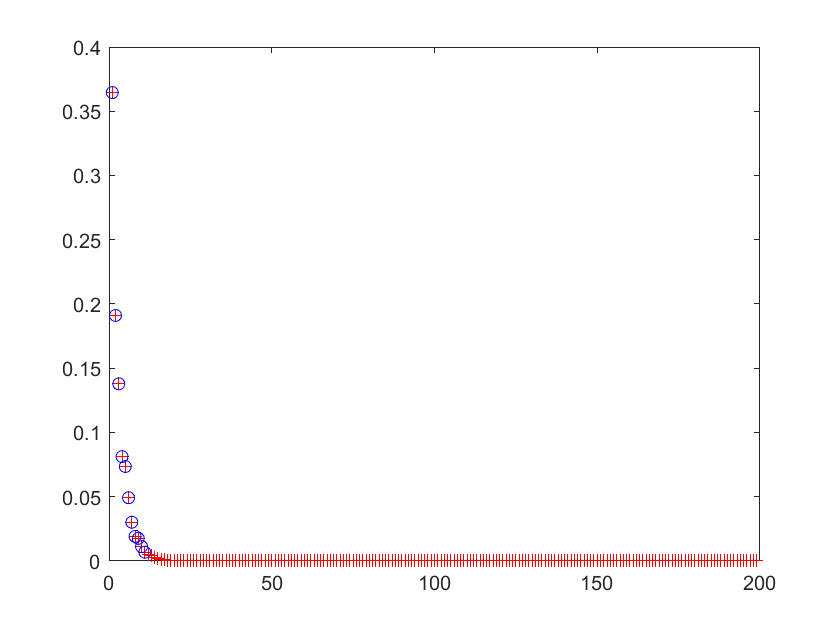


figure;
plot(dmd.singularValues/sum(dmd.singularValues),'r+')
hold on
plot(dmd.truncatedSingularValues/sum(dmd.singularValues),'bo')

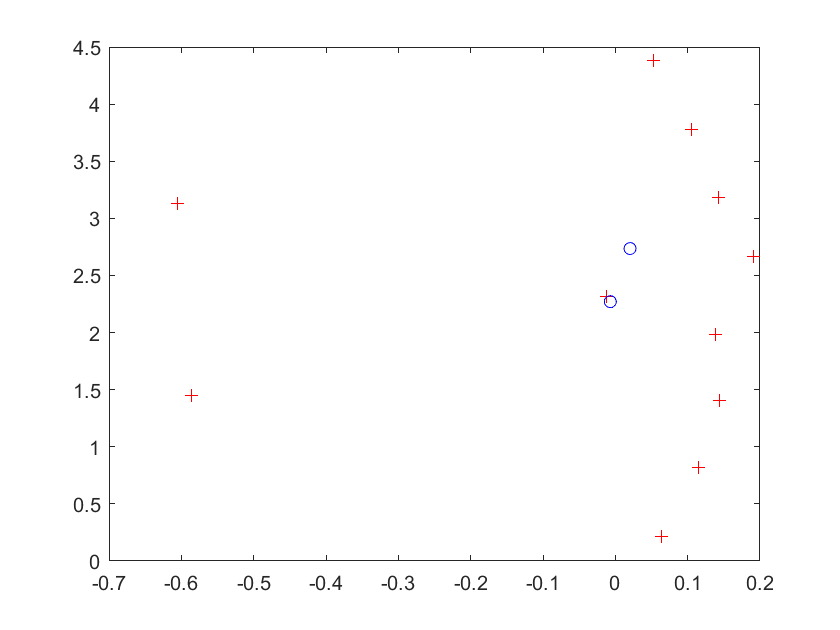


figure
plot(dmd.continuousTimeEigenValues,'+r')
hold on
plot(omega,'ob')

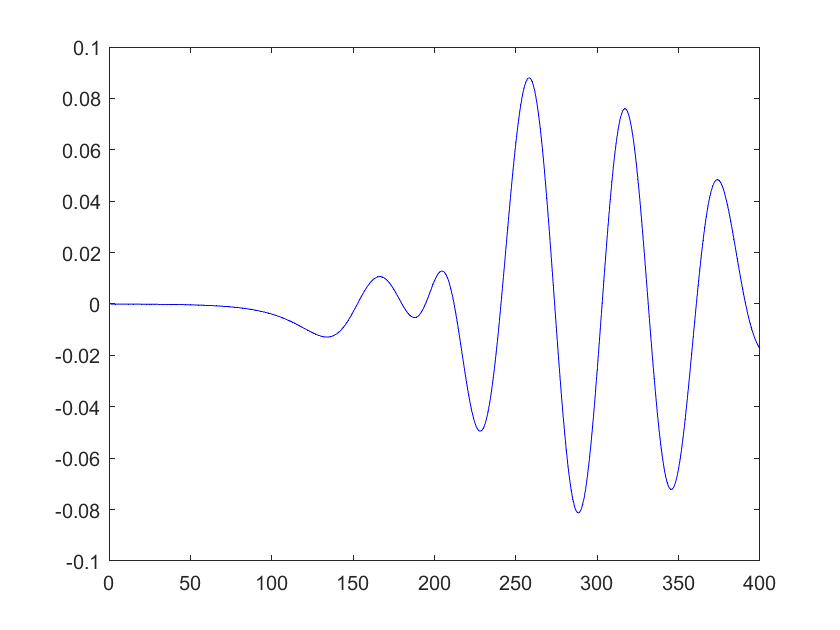

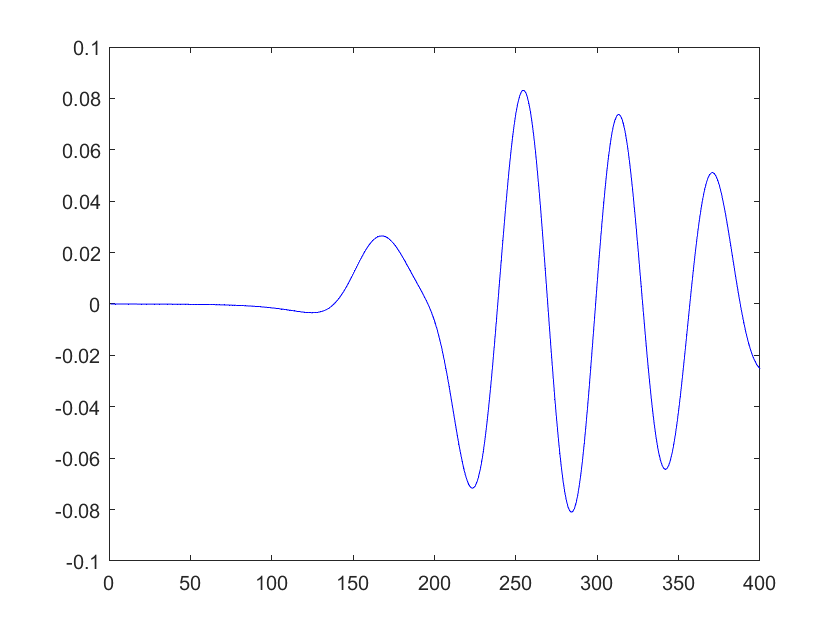

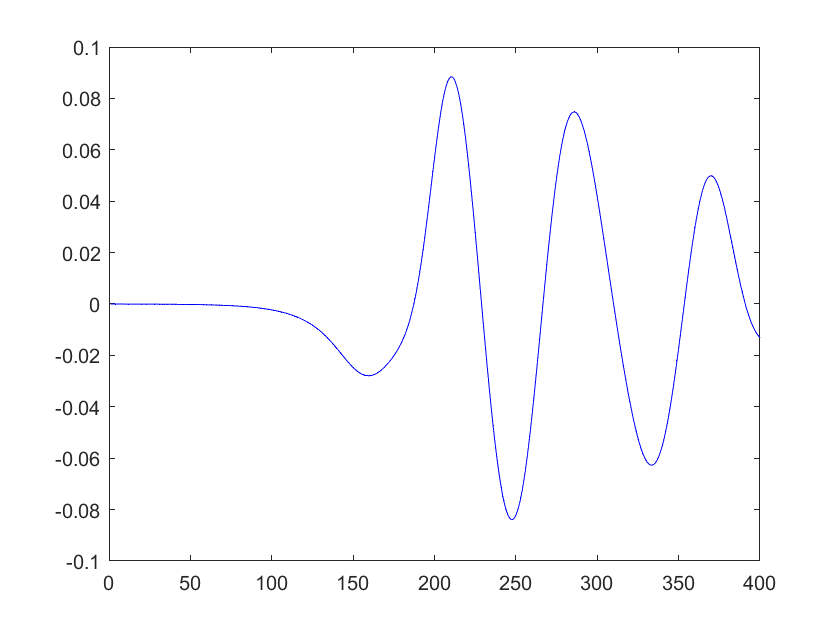

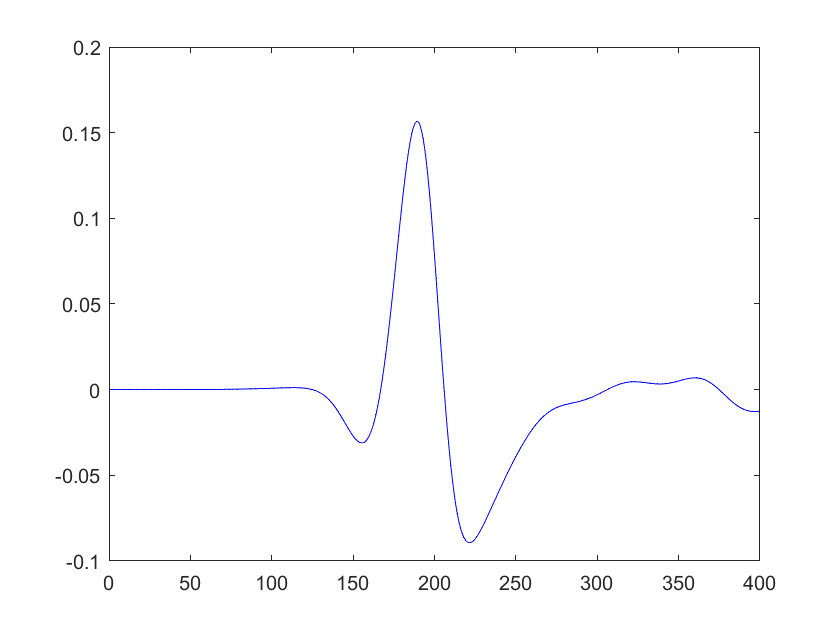

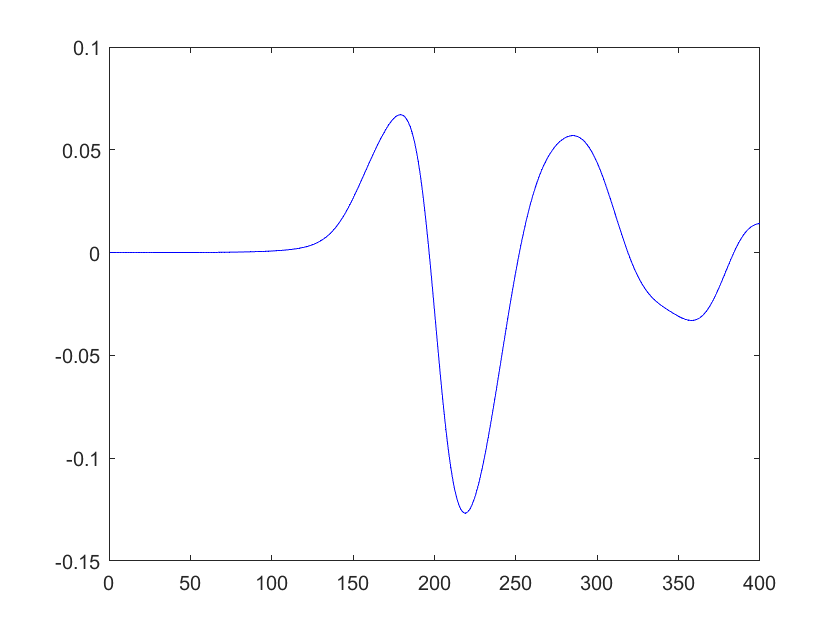

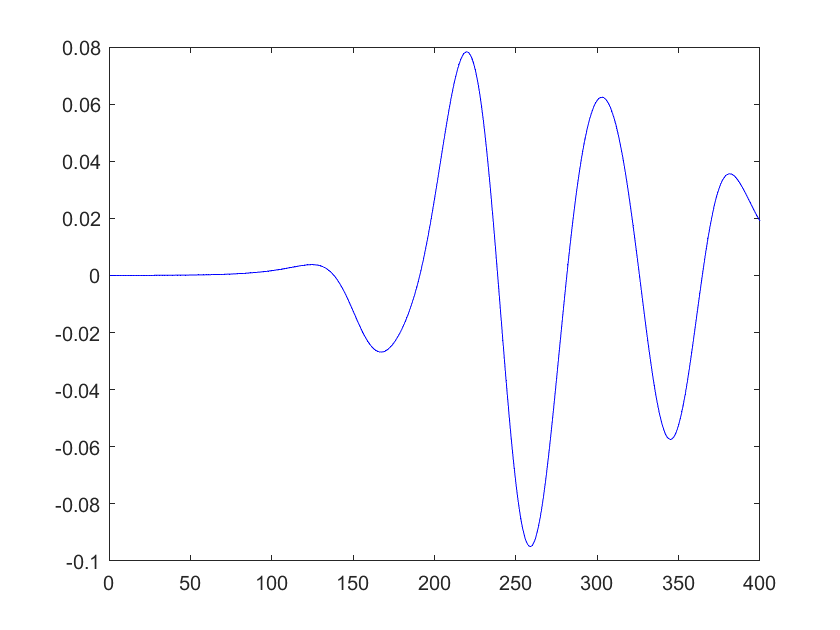

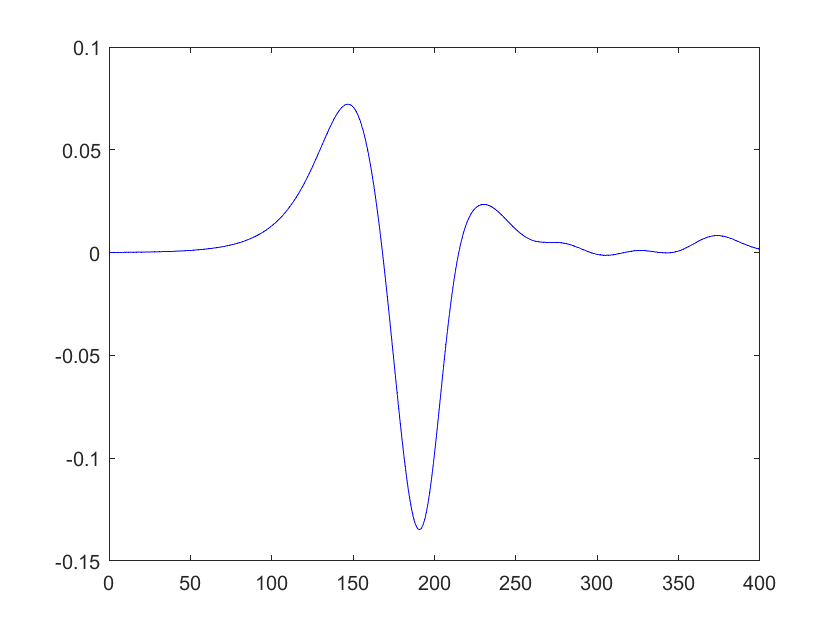

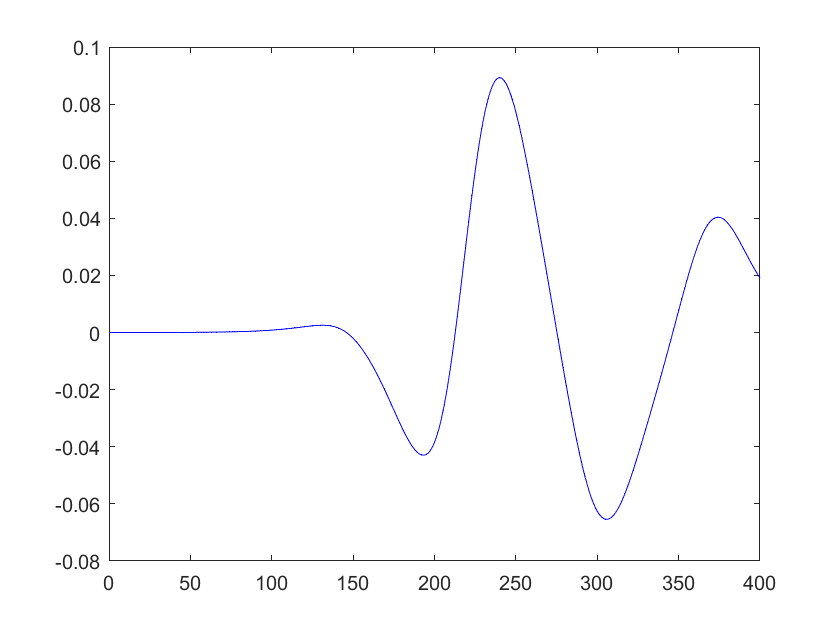


for i = 1:min(size(dmd.modes,2),10)
    figure
    plot(real(dmd.modes(:,i)),"b");
end


modeFrequency = dmd.continuousTimeEigenValues / (2*pi);